Computer vision Lab 2; edge detection, Part 1-4

Question 1

disp('Question 1')

Question 1



tools = few256;
% Sobel operator
deltax=[1 0 -1; 2 0 -2; 1 0 -1];
deltay=[1 2 1; 0 0 0 ; -1 -2 -1];

dxtools = conv2(tools, deltax, "valid");
dytools = conv2(tools, deltay, "valid");

disp(['Size of original: ',num2str(size(tools))])

Size of original: 256  256


disp(['Size of dxtools: ',num2str(size(dxtools))])

Size of dxtools: 254  254


disp(['Size of dytools: ',num2str(size(dytools))])

Size of dytools: 254  254


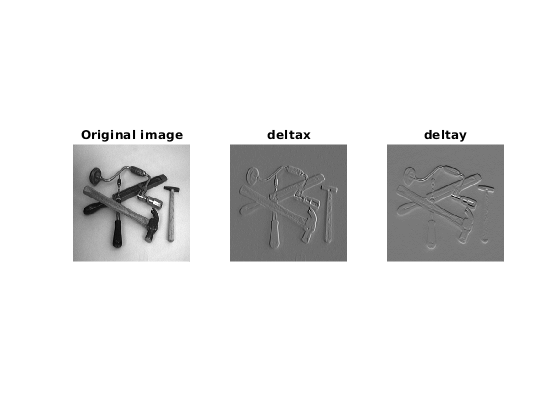

figure()
subplot(1,3,1)
showgrey(tools)
title('Original image')


subplot(1,3,2)
showgrey(dxtools)
title('deltax')


subplot(1,3,3)
showgrey(dytools)
title('deltay')

**Question 1: *****What do you expect the results to look like and why? Compare the size of dxtools with the size of tools. Why are these sizes different? ***

Anwser: We expect the result to be a image where only the edges are emphasized. This is because the sobel operator computes the gradient of the image intensity function. The deltax operator emphasizes the lines in the y-direction and vice-versa. The size of dxtools and dytools are 2 pixels smaller in width and height, this is because the conv2 function used only returns parts that are computed without the zero-padded edges if the valid flag is raised.

Question 2 & Question 3

disp('Question 2 & Question 3')

tools = few256;
god= godthem256;
outpic=Lv(tools,1);
outpic2=Lv(god,1);
gradmagntools = sqrt(outpic2);

figure()
histogram(gradmagntools)
title('Histogram of image')

figure()
subplot(1,3,1)
showgrey(gradmagntools)
title('Image without threshold')

threshold=80
subplot(1,3,3)
showgrey((gradmagntools - threshold) > 0)
title(['Image with thershold ',num2str(threshold)])


**Question 2: *****Is it easy to find a threshold that results in thin edges? Explain why or why not!***

Anwser: It is hard because thin edges in one part of the image may result in other parts not showing up at all and if more edges are included some of the edges will be thicker.

**Question 3:***** Does smoothing the image help to find edges?***

Anwser: Smoothing the image removes high frequency noise and makes the edges easier to see. Too much smoothing removes information about the edges.

Question 4

disp('Question 4')

house = godthem256;

t=[0.0001 1 4 16 64];

figure()
subplot(2,3,1)
showgrey(house)
title('Original image')
subplot(2,3,2)
contour(Lvvtilde(house,t(1),"same"), [0 0]);
title(['Smoothing, t= ',num2str(t(1))])
axis("image");
axis("ij");

subplot(2,3,3)
contour(Lvvtilde(house,t(2),"same"), [0 0]);
title(['Smoothing, t= ',num2str(t(2))])
axis("image");
axis("ij");

subplot(2,3,4)
contour(Lvvtilde(house,t(3),"same"), [0 0]);
title(['Smoothing, t= ',num2str(t(3))])
axis("image");
axis("ij");

subplot(2,3,5)
contour(Lvvtilde(house,t(4),"same"), [0 0]);
title(['Smoothing, t= ',num2str(t(4))])
axis("image");
axis("ij");

subplot(2,3,6)
contour(Lvvtilde(house,t(5),"same"), [0 0]);
title(['Smoothing, t= ',num2str(t(5))])
axis("image");
axis("ij");



**Question 4: *****What can you observe? Provide explanation based on the generated images.***

Anwser: The images without much smoothing conatins large amount of high frequency content. This makes the images detailed but noisy. The more smoothed images contains less details but its easier to see the edges. If it is too smoothed most of the edges are removed. The lines are thinner than the first derivative, this is because only max and min values are plotted.

Question 5

disp('Question 5')

inpic=few256;

t=[0.0001 1 4 16 64];

figure()
subplot(2,3,1)
showgrey(inpic)
title('Original image')

subplot(2,3,2)
showgrey(Lvvvtilde(inpic,t(1), 'same') < 0)
title(['Smoothing lvvvtilde, t= ',num2str(t(1))])

subplot(2,3,3)
showgrey(Lvvvtilde(inpic,t(2), 'same') < 0)
title(['Smoothing lvvvtilde, t= ',num2str(t(2))])

subplot(2,3,4)
showgrey(Lvvvtilde(inpic,t(3), 'same') < 0)
title(['Smoothing lvvvtilde, t= ',num2str(t(3))])

subplot(2,3,5)
showgrey(Lvvvtilde(inpic,t(4), 'same') < 0)
title(['Smoothing lvvvtilde, t= ',num2str(t(4))])

subplot(2,3,6)
showgrey(Lvvvtilde(inpic,t(5), 'same') < 0)
title(['Smoothing lvvvtilde, t= ',num2str(t(5))])

**Question 5: *****Assemble the results of the experiment above into an illustrative collage with the subplot command. Which are your observations and conclusions?***

Anwser: For small values of the variance we get more noise on the other hand for large variance the area of which Lvvv<0 holds will be larger due to the gaussian smoothing and will therefor give thiccer edges.

**Question 6:**  ***How can you use the response from Lvv to detect edges, and how can you improve the result by using Lvvv?***

Anwser:  By using Lvv we can detect maximums and minimums, with the constraint Lvvv<0 we get the areas for where there are a maximums. By combining Lvv with Lvvv we can get the maximum and the exact point for where the edge take place.

Part 5-6

Question 7

disp('Question 7')

Question 7


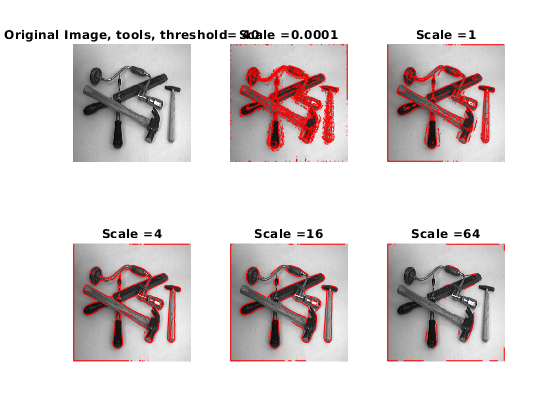

scale=[0.0001 1 4 16 64];
inpic=few256;
figure(1001)
subplot(2,3,1)
showgrey(inpic)
title(['Original Image, tools, threshold= ', num2str(threshold)])

for i=1:5
threshold=50;
curves=extractedge(inpic, scale(i),threshold);
subplot(2,3,i+1)
overlaycurves(inpic, curves);
title(['Scale =', num2str(scale(i))])

end

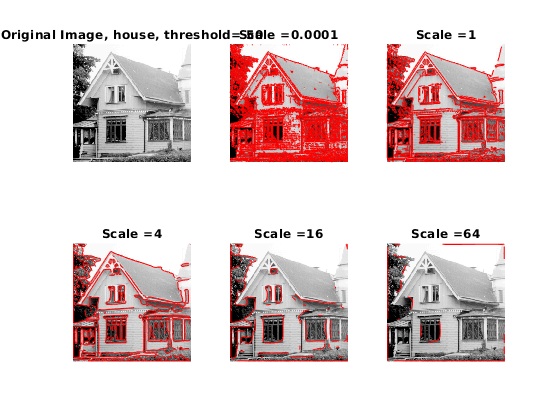


inpic=godthem256;
threshold=50;
figure(1000)
subplot(2,3,1)
showgrey(inpic)
title(['Original Image, house, threshold= ', num2str(threshold)])

for i=1:5
curves=extractedge(inpic, scale(i),threshold);
subplot(2,3,i+1)
overlaycurves(inpic, curves);
title(['Scale =', num2str(scale(i))])
end

**Question 7: *****Present your best results obtained with extractedge for house and tools.***

Anwser: For the tools set we think that when scale= 4 we get the best result whereas for the house we think that when scale= 1 give the best result where we, although a bit noisy, find the most edges.

Question 8

disp('Question 8, 9, 10')

Question 8, 9, 10


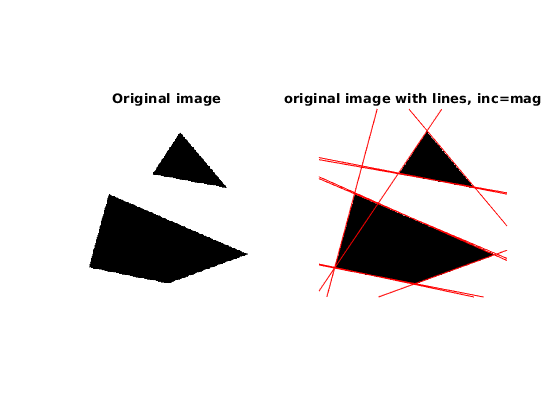

%close all
inpic =houghtest256;
threshold=40;
scale=8; 
ntheta=180;nlines=10;
verbose=3; %(0 for silent, 1 for plot of lines w. original, 2 for acc image, 3 to include magnitude in calculation) 


Diag=sqrt((size(inpic,2)-1)^2+(size(inpic,1)-1)^2);
nrho=(2*ceil((Diag/1)))+1;
outpic=Lv(inpic,1);
gradmagntools = sqrt(outpic);


[h,acc]=houghedgeline(inpic,scale,gradmagntools,threshold,nrho,ntheta,nlines,verbose);

**Question 8:**Identify the correspondences between the strongest peaks in the accumulator and line segments in the output image. Doing so convince yourself that the implementation is correct. Summarize the results in one or more figures. Then apply the same procedure to the test image houghtest256. Show the results of your procedure houghedgeline applied to the images few256, phonecalc256 and godthem256.

Anwser: See images.

**Question 9.:***** How do the results and computational time depend on the number of cells in the accumulator?***

Anwser: Increasing  the accumulator space by increasing ntheta will increase comptutational time but will give better solutions.

**Question 10: *****How do you propose to do this? Try out a function that you would suggest and see if it improves the results. Does it?***

Anwser: Instead of letting increment=1 we instead let increment=magnitude(x,y) where the magnitude is given by Lv(inpic,shape). The magnitude increment puts more significance on the contrast of the edge. It can therefore better detect smaller but more clear edges. The  increment=1 puts more weight on the length of an edge and therefore better can detect longer but more gradual edges. Squaring the magnitude further increases this effect. With magnitude incriment the short white pillars with a black background in the lower left corner of the picture are detected but not the grey long roof with the white background.